# Notch Filter Equation

## 
$$\text{TF}_{notchFIlter} = \frac{s^2 + 2 \zeta \omega_n \cdot s + \omega_n^2}{\omega_n^2} \cdot 
\frac{a\cdot \omega_n}{s + a \cdot \omega_n} \cdot \frac{\omega_n / a}{s + \omega_n/a} \\
\text{when: } \\ \zeta - \text{affects notch depth} \\
\omega_n - \text{notch frequency} \\
a - \text{notch width} $$


zeta = 0;
a = 4.4;
freq = 54;
omega = 2*pi*freq;

TF1 = tf([1 2*zeta*omega omega^2], omega^2);
TF2 = tf(a*omega, [1 a*omega]);
TF3 = tf(omega/a, [1 omega/a]);
TF = TF1*TF2*TF3;

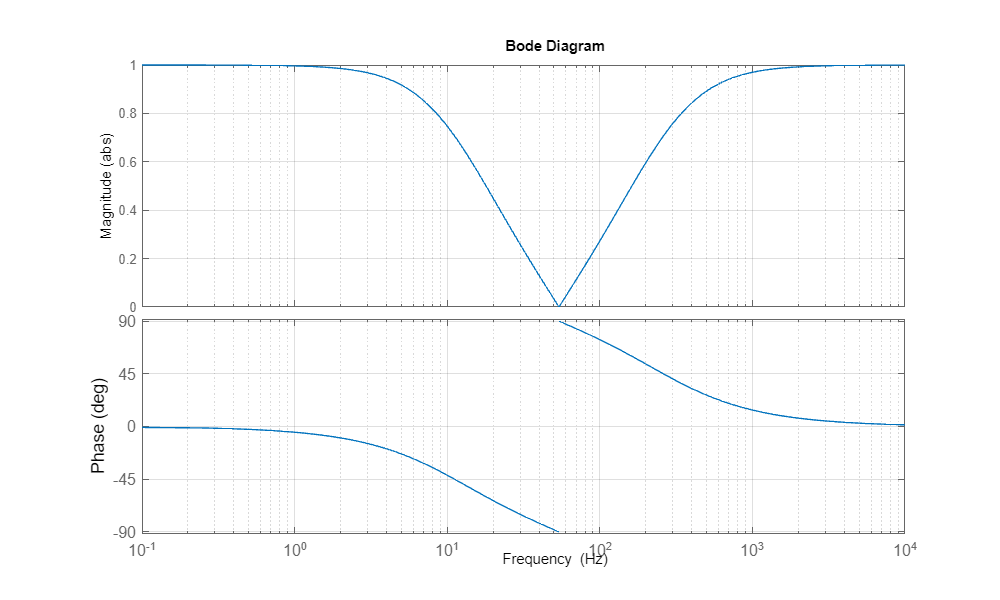

figure('Position',[0 0 1000 600])
bodeplot(TF)
grid minor
set(gca, 'Fontsize', 12)